Suponga que un sensor de distancia instalado en un robot móvil detecta un obstáculo en la posición (1,3). Este robot se encuentra en la posición (2,0) en el marco inercial (o global) con una orientación de pi/3. ¿Cuáles son las coordenadas globales del obstáculo?� 

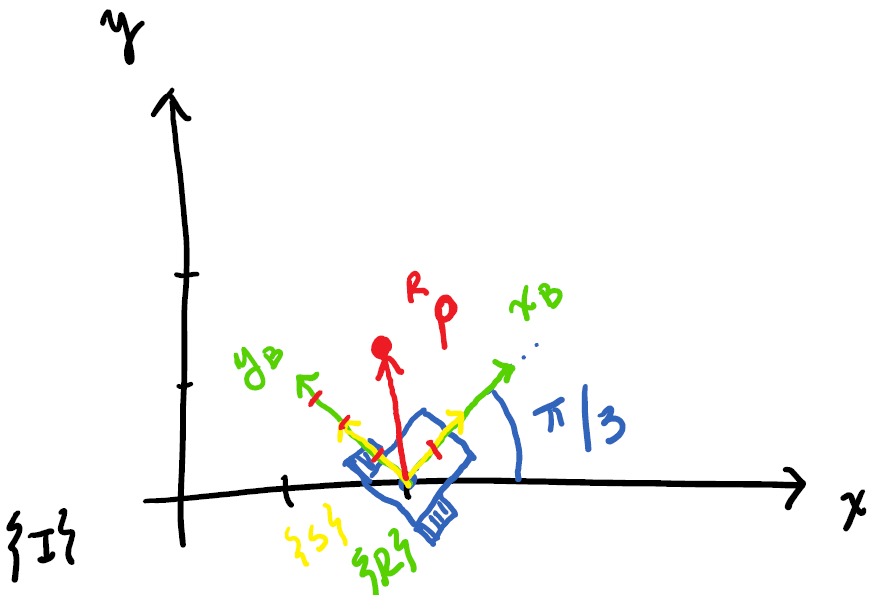

% Información provista por el problema
Bp = [1; 3]; % punto visto desde el sensor instalado en el robot
Io_B = [2; 0]; % posición del robot
theta = pi/3; % orientación del robot

Con la información dada, se encuentra la matriz de rotación y la matriz de transformación homogénea

IR_B = [cos(theta), -sin(theta); sin(theta), cos(theta)]

IR_B =     0.5000   -0.8660
    0.8660    0.5000


IT_B = [IR_B, Io_B; 0, 0, 1]

IT_B =     0.5000   -0.8660    2.0000
    0.8660    0.5000         0
         0         0    1.0000


Se pasan los vectores a coordenadas homogéneas

Bp_hom = [Bp; 1]

Bp_hom =      1
     3
     1


Se aplica el cambio de coordenadas mediante la matriz de transformación homogénea y multiplicación de matrices

Ip_hom = IT_B * Bp_hom

Ip_hom =    -0.0981
    2.3660
    1.0000


Se extrae la posición global del obstáculo del vector de coordenadas homogéneas

Ip = Ip_hom(1:2)

Ip =    -0.0981
    2.3660
